%testing
%fs can not be modified during runtime, manually set fs in simulink!!
%Fs = 4000 %defined in simulink

Fs = 4000

%Ts = 1/Fs %defined in simulink

Ts = 2.5000e-04


SampleFreq = "fs_" + 4000 + "_Hz";

Path = "HardwareMeasurements/"  ...
        + "ProtoLab_setup_45" ...
        + "/" + SampleFreq 

Path = "HardwareMeasurements/ProtoLab_setup_45/fs_4000_Hz"

Path_2110 = "HardwareMeasurements/"  ...
        + "ProtoLab_setup_45_2110" ...
        + "/" + SampleFreq 

Path_2110 = "HardwareMeasurements/ProtoLab_setup_45_2110/fs_4000_Hz"

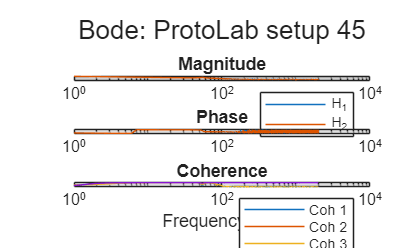

ans =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [1 1 1]
    Position: [323 225 560 337.2667]
       Units: 'pixels'

  Show all properties


 PlotProcessedData([ ...
     {GetProcessedData(Path,"3_point",4);"H"}... 
     {GetProcessedData(Path_2110,"3_point",1);"H"}...
    %{GetProcessedData(Path,"3_point",1);"H"} ...
    %{GetProcessedData(Path,"3_point",2);"H"} ...
    %{GetProcessedData(Path,"3_point",3);"H"} ...
    %{GetProcessedData(Path,"3_point",4);"H"} ...
     ], ...
     "ProtoLab setup 45")

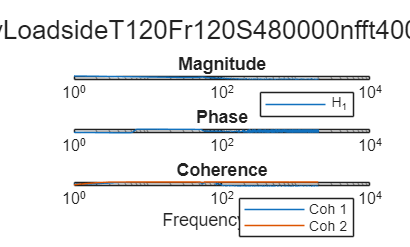

ans =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [323 225 560 337.2667]
       Units: 'pixels'

  Show all properties


L = Data.calculatedData.L;
H = Data.calculatedData.H;
f = Data.calculatedData.f;
Coh = Data.calculatedData.Coh;  

mybode(f,H,Coh,replace(Data.FileName,'_',''))

% ------------------- Controller (Run before simulink) ----------------------------%
s = tf('s');
Kp = 0.02%10;

Kp = 0.0200

Kd = 0.002%0.1;

Kd = 0.0020


f_filt = 200;
b_filt = 0.7;

C_pd = (Kp + s*Kd);
C_filter = (1)/((1/(2*pi*f_filt)^2)*s^2+((2*b_filt)/(2*pi*f_filt))*s+1);

C_total = C_pd * C_filter;

% Automated measurements per Fs
% Set the required sample frequency manually in the simulink file before running on the hardware!!
include_processing = 1 % if set to 0, only the measurements are taken and stored

include_processing = 1


% --------------------- Set before measurement ----------------------%
%Measurment Name
Exercise = "ProtoLab_setup_45_2110";
Measurement = "velocity_Load_side";
SampleFreq = "fs_" + Fs + "_Hz";

Path = "HardwareMeasurements/"  ...
        + Exercise ...
        + "/" + SampleFreq

Path = "HardwareMeasurements/ProtoLab_setup_45_2110/fs_4000_Hz"


N_measurements = 1

N_measurements = 1

Trun = [120] %measurement durations

Trun = 120

frames = [120] %amount of frames

frames = 120

variance = '0.1';

%Measurement Type (1: Closed_loop, 0: Open_loop)
measurementType = 1;

%Open loop settings
% 1) d
% 2) y
% 3) u
% 4) e
% 5) r
in = 3;
out = 2;

% ------------------ Calculated by program --------------------------%

if(isempty(C_total))
    error("Controller not defined");
end

samples = Trun*Fs; %measurement size per duration(samples)
nfft = zeros(length(Trun),length(frames));
for i = 1 : length(Trun)
    nfft(i,:) = Trun(i)./frames*Fs;
    for j = 1 : length(nfft(i,:))
        if (nfft(i,j) - floor(nfft(i,j))) > 0 %not an integer valeu
         warning("nfft("+i+","+j+") is not an integer value: " + nfft(i,j));
         nfft(i,j) = floor(nfft(i,j));
         warning("flooring to nfft(" + i + "," + j + ") = " + nfft(i,j));
        end
    end
end

Fres = Fs./nfft

Fres = 1


%start running the automated measurements for n cycles
for cycles = 1 : N_measurements
    %Measuring, take 1 measurement of the longest FRF time
    tic
    [d_raw,y_raw,u_raw,e_raw,r_raw] = StartFRFMeasurement(p,samples(end),variance,'Hardware_FRF_setup');
    disp("Measurment Done!" + toc)

    %Store raw data
    measurementName = "Cycle" + cycles + "_" + Measurement + "_T" + Trun(end) + "_S" + samples(end);
    saveMeasurement(...
    struct("runtime", Trun(end), "fs", Fs, "samples", samples(end)), ...%settings
    struct("r", r_raw, "d",d_raw,"u",u_raw,"e",e_raw,"y",y_raw), ... %signals
    [], ...%calculatedData
    Path +'/measured_signals/'+ measurementName);
    
    for i = 1 : length(Trun)
        %Split measurement in smaller chunkes of samples
        d = d_raw(1:samples(i));
        y = y_raw(1:samples(i));
        u = u_raw(1:samples(i));
        e = e_raw(1:samples(i));
        r = r_raw(1:samples(i));
    
        %store seperated measurements
        measurementName = "Cycle" + cycles + "_" + Measurement + "_T" + Trun(i) + "_S" + samples(i);
        saveMeasurement(...
        struct("runtime", Trun(i), "fs", Fs, "samples", samples(i)), ...%settings
        struct("r", r, "d",d,"u",u,"e",e,"y",y), ... %signals
        [], ...%calculatedData
        Path +'/seperated_measured_signals/'+ measurementName);
    
        %processing
        if(include_processing ~= 0)
            for j = 1 : length(frames)
                noverlap = floor(nfft(i,j)/2);
                window = hann(nfft(i,j));
    
                switch (measurementType)
                    case 1 % Closed_loop
                        % 2-point method
                        [f, H, S, L, Coh, C_resp] = twoPoint(d, u, r, C_total, window, noverlap, nfft(i,j), Fs);
                        
                        %store 2-point data
                        measurementName = "Cycle" + cycles + "_" + Measurement + "_T" + Trun(i) + "_Fr" + frames(j) + "_S" + samples(i) + "_nfft" + nfft(i,j);
                        saveMeasurement(...
                        struct("runtime", Trun(i), "fs", Fs, "samples", samples(i),"nfft", nfft(i,j),"noverlap", noverlap,"window", window, "fres", Fres(i,j), "C_res", C_resp), ...%settings    
                        struct("r", r, "d",d,"u",u,"e",e,"y",y), ... %signals
                        struct("f",f,"H",H,"S",S, "L", L,"Coh",Coh, "C",C_resp), ...%calculatedData
                        Path + '/processed_signals/2_point/'+ measurementName);
        
                        % 3-point method
                        [f, H, S, Coh, C_est, L_est] = threePoint(d,e,u,window,noverlap,nfft(i,j),Fs);
        
                        %store 3-point data
                        measurementName = "Cycle" + cycles + "_" + Measurement + "_T" + Trun(i) + "_Fr" + frames(j) + "_S" + samples(i) + "_nfft" + nfft(i,j);
                        saveMeasurement(...
                        struct("runtime", Trun(i), "fs", Fs, "samples", samples(i),"nfft", nfft(i,j),"noverlap", noverlap,"window", window, "fres", Fres(i,j),"C_res", C_est), ...%settings    
                        struct("r", r, "d",d,"u",u,"e",e,"y",y), ... %signals
                        struct("f",f,"H",H,"S",S,"L",L_est, "Coh",Coh, "C",C_est), ...%calculatedData
                        Path + '/processed_signals/3_point/'+ measurementName);
                    otherwise % Open_loop
                        signals = [d,y,u,e,r];

                        %H = out/in
                        [H_est,f_est] = tfestimate(signals(in),signals(out),window,noverlap,nfft(i,j),Fs);
                        [Ch, ~] = mscohere(signals(in),signals(out),window,noverlap,nfft(i,j),Fs);

                        %store open loop frf data
                        measurementName = "Cycle" + cycles + "_" + Measurement + "_T" + Trun(i) + "_Fr" + frames(j) + "_S" + samples(i) + "_nfft" + nfft(i,j);
                        saveMeasurement(...
                        struct("runtime", Trun(i), "fs", Fs, "samples", samples(i),"nfft", nfft(i,j),"noverlap", noverlap,"window", window, "fres", Fres(i,j)), ...%settings    
                        struct("r", r, "d",d,"u",u,"e",e,"y",y), ... %signals
                        struct("f",f_est,"H",H_est,"S",[],"L",[], "Coh",Ch, "C",[]), ...%calculatedData
                        Path + '/processed_signals/Open_loop/'+ measurementName);

                end
            end
        end
    end
end

Starting measurement with white noise on the disturbance.
If you are planning on doing an FRF measurement, 
think carefully about the signals you need and consider open/closed loop.
Starting the measurement, should take 120 seconds to collect 480000 Samples.
Measurement finished.
Retrieving measurement file(s).
Files retrieved.


Measurment Done!147.723
